## Aim 1 heatmap of all neurons vs odors, 

nwb = nwbRead('MATLAB/Neural signal project/sub-8_ses-20200204T180138_ophys.nwb');

ophys = get(nwb.processing, 'ophys');
fluorescence = get(ophys.nwbdatainterface, 'Fluorescence');

roi_response = get(fluorescence.roiresponseseries, 'Plane_0');
dff = roi_response.data.load();              

timestamps = roi_response.timestamps.load(); 

odor = get(nwb.stimulus_presentation, 'odor');
stim_timestamps = odor.timestamps.load();  
stim_labels = odor.data.load();            

% 確保 stim_labels 與 stim_timestamps 為 column vector
stim_labels = stim_labels(:);
stim_timestamps = stim_timestamps(:);

% 找出氣味變化點（onset）
odor_onset_idx = find([true; diff(stim_labels) ~= 0]);

% 抓出 onset 對應時間與氣味 label
odor_onset_times = stim_timestamps(odor_onset_idx);
odor_onset_labels = stim_labels(odor_onset_idx);

% 篩掉無效 label（背景或 NaN）
valid_mask = ~isnan(odor_onset_labels) & odor_onset_labels >= 0;
odor_onset_times = odor_onset_times(valid_mask);
odor_onset_labels = odor_onset_labels(valid_mask);

% 👉 可選：過濾太短間隔（如果你發現某些氣味持續時間太短）
% min_interval = 3; % 單位秒
% keep = [true; diff(odor_onset_times) > min_interval];
% odor_onset_times = odor_onset_times(keep);
% odor_onset_labels = odor_onset_labels(keep);



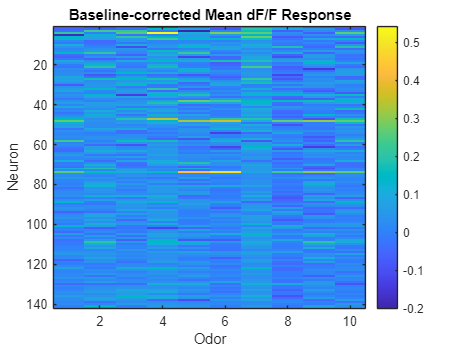

resp_window = [0, 2];         % 分析視窗（刺激後）
baseline_window = [-1, 0];    % 基線視窗（刺激前）

fps = 1 / median(diff(timestamps));
resp_frames = round(resp_window * fps);
base_frames = round(baseline_window * fps);

n_cells = size(dff, 1);
n_odors = 10;
trial_responses = zeros(n_cells, length(odor_onset_times));

for i = 1:length(odor_onset_times)
    t0 = odor_onset_times(i);
    [~, onset_idx] = min(abs(timestamps - t0));
    
    base_idx = onset_idx + base_frames(1):onset_idx + base_frames(2);
    resp_idx = onset_idx + resp_frames(1):onset_idx + resp_frames(2);

    if min(base_idx) < 1 || max(resp_idx) > size(dff, 2)
        trial_responses(:, i) = NaN;
        continue;
    end

    F0 = mean(dff(:, base_idx), 2);
    F_resp = mean(dff(:, resp_idx), 2);
    dff_trial = (F_resp - F0) ./ F0;

    trial_responses(:, i) = dff_trial;
end

% 平均每個氣味反應
mean_responses = zeros(n_cells, n_odors);
for odor = 1:n_odors
    idx = find(odor_onset_labels == odor);
    mean_responses(:, odor) = mean(trial_responses(:, idx), 2, 'omitnan');
end

% heatmap
figure;
imagesc(mean_responses);
xlabel('Odor'); ylabel('Neuron');
title('Baseline-corrected Mean dF/F Response');
colorbar;

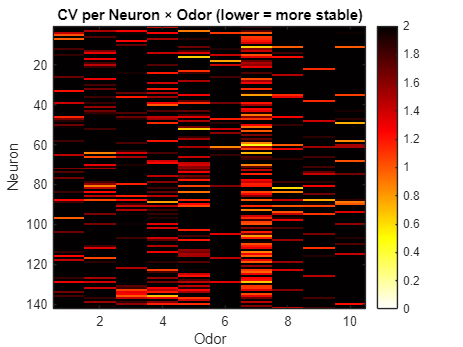

% 參數
[n_neurons, ~] = size(trial_responses);
n_odors = 10;

% 初始化 CV 矩陣
CV_per_odor = nan(n_neurons, n_odors);

% 計算每個 neuron 對每個 odor 的 CV
for neuron = 1:n_neurons
    for odor = 1:n_odors
        idx = find(odor_onset_labels == odor);
        responses = trial_responses(neuron, idx);
        responses = responses(~isnan(responses));

        if numel(responses) >= 3
            mu = mean(responses);
            sigma = std(responses);
            CV_per_odor(neuron, odor) = sigma / (abs(mu) + 1e-6);
        end
    end
end

% 🔍 繪製 heatmap（CV 越小越穩定）
figure;
imagesc(CV_per_odor, [0 2]);  % 根據你的數值範圍可調整 upper limit
colormap(flipud(hot));        % 小值亮、越不穩定越暗
colorbar;
xlabel('Odor');
ylabel('Neuron');
title('CV per Neuron × Odor (lower = more stable)');

% 🔍 額外分析：找出反應強且穩定的 neuron × odor 組合
high_response_threshold = 0.1;  % 反應強度 ΔF/F 閾值
max_cv_threshold = 0.8;         % 變異係數（穩定性）閾值

% 找出強且穩定的 neuron-odor 組合
results = [];

for neuron = 1:n_cells
    for odor = 1:n_odors
        trial_idx = find(odor_onset_labels == odor);
        trials = trial_responses(neuron, trial_idx);

        if numel(trials) < 3
            continue;
        end

        mean_dff = mean(trials, 'omitnan');
        std_dff = std(trials, 'omitnan');
        cv_dff = std_dff / (abs(mean_dff) + 1e-6);  % 防止除 0

        if mean_dff > high_response_threshold && cv_dff < max_cv_threshold
            results = [results; neuron, odor, mean_dff, std_dff, cv_dff];
        end
    end
end

% ✅ 確保即使為空，也能建表格
if isempty(results)
    results = nan(0,5);  % 建立空表格：0 行 5 欄
end

T = array2table(results, ...
    'VariableNames', {'Neuron', 'Odor', 'Mean_dF_F', 'Std_dF_F', 'CV_dF_F'});

disp('✅ Neuron-Odor combinations with strong and stable responses:');

✅ Neuron-Odor combinations with strong and stable responses:


disp(T);

    Neuron    Odor    Mean_dF_F    Std_dF_F    CV_dF_F
    ______    ____    _________    ________    _______

      18        6      0.17857     0.13803     0.77294
      35        7      0.13147     0.10308     0.78404
      49       10      0.16296     0.12075     0.74097
      89        4      0.13561     0.10798     0.79623



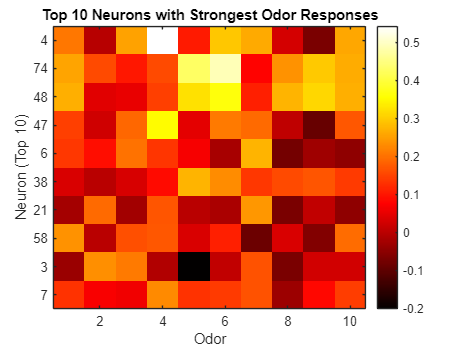

% 🎯 取出 max odor response per neuron，排序後取前10
max_response_per_neuron = max(mean_responses, [], 2);  % 每個 neuron 的最大反應
[~, sorted_idx] = sort(max_response_per_neuron, 'descend');
top_n = 10;
top_neuron_idx = sorted_idx(1:min(top_n, length(sorted_idx)));  % 防止少於10個

% 📊 擷取 top 10 neuron 的 mean_responses
top10_responses = mean_responses(top_neuron_idx, :);

% 🎨 畫 heatmap
figure;
imagesc(top10_responses);
xlabel('Odor');
ylabel('Neuron (Top 10)');
yticks(1:length(top_neuron_idx));
yticklabels(top_neuron_idx);  % 顯示 neuron 編號
title('Top 10 Neurons with Strongest Odor Responses');
colorbar;
colormap('hot');

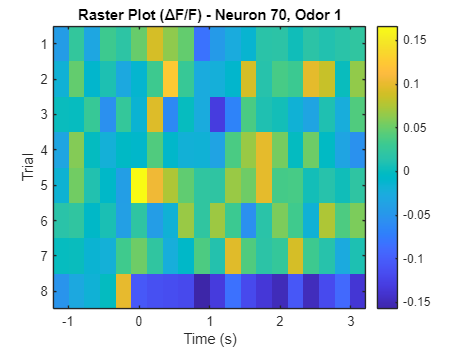

neuron_id = 70;    
target_odor = 1;  
window = [-1, 3];  % -1秒到+3秒

fps = 1 / median(diff(timestamps));
win_frames = round(window(1) * fps):round(window(2) * fps);
t_axis = win_frames / fps;

trial_idx = find(odor_onset_labels == target_odor);
n_trials = length(trial_idx);
raster_data = zeros(n_trials, length(win_frames));

for i = 1:n_trials
    t0 = odor_onset_times(trial_idx(i));
    [~, onset_idx] = min(abs(timestamps - t0));
    idx = onset_idx + win_frames;

    if min(idx) < 1 || max(idx) > length(timestamps)
        raster_data(i, :) = NaN;
        continue;
    end

    % ✅ baseline normalization
    baseline_idx = idx(t_axis < 0);  % 用刺激前的時間作為 baseline
    F0 = mean(dff(neuron_id, baseline_idx), 'omitnan');
    raster_data(i, :) = (dff(neuron_id, idx) - F0) / F0;
end

% 🔍 Raster plot（每一列是一個 trial 的 ΔF/F）
figure;
imagesc(t_axis, 1:n_trials, raster_data);
xlabel('Time (s)'); ylabel('Trial');
title(sprintf('Raster Plot (ΔF/F) - Neuron %d, Odor %d', neuron_id, target_odor));
colorbar;

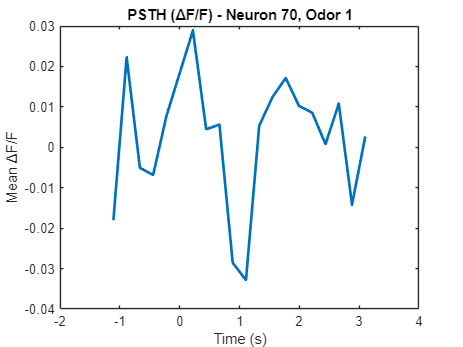


% 📊 PSTH（平均 ΔF/F trace across trials）
mean_trace = nanmean(raster_data, 1);
figure;
plot(t_axis, mean_trace, 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Mean ΔF/F');
title(sprintf('PSTH (ΔF/F) - Neuron %d, Odor %d', neuron_id, target_odor));

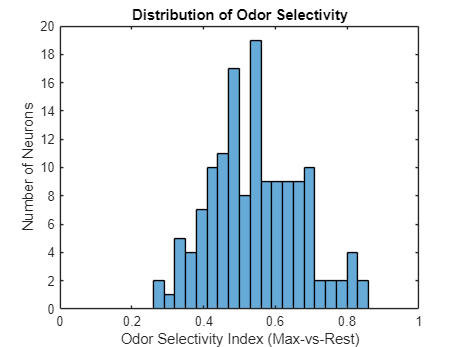

% ✅ 1. 計算 OSI（Max-vs-Rest 版本）
n_cells = size(mean_responses, 1);
OSI = zeros(n_cells, 1);

for n = 1:n_cells
    responses = mean_responses(n, :);
    
    % 修正：將負值設為0，避免 denominator 太小或出現錯誤比值
    responses(responses < 0) = 0;

    [r_max, max_idx] = max(responses);
    rest = responses;
    rest(max_idx) = [];
    r_mean_others = mean(rest, 'omitnan');

    OSI(n) = (r_max - r_mean_others) / (r_max + r_mean_others + 1e-6);  % 防除 0
end


% ✅ 2. 畫 OSI histogram
figure;
histogram(OSI, 20);
xlim([0 1])
xlabel('Odor Selectivity Index (Max-vs-Rest)');
ylabel('Number of Neurons');
title('Distribution of Odor Selectivity');


% ✅ 3. 建立 OSI 表格（排序找前10名）
[sorted_osi, sorted_idx] = sort(OSI, 'descend');
top_n = 10;
top_neuron_idx = sorted_idx(1:min(top_n, length(sorted_idx)));
top_osi_values = sorted_osi(1:min(top_n, length(sorted_idx)));

OSI_table = table(top_neuron_idx, top_osi_values, ...
    'VariableNames', {'Neuron', 'Max_vs_Rest_OSI'});
disp('🔍 Top OSI Neurons (Max-vs-Rest):');

🔍 Top OSI Neurons (Max-vs-Rest):


disp(OSI_table);

    Neuron    Max_vs_Rest_OSI
    ______    _______________

     102          0.84433    
      61          0.84193    
      87          0.81343    
      71           0.8103    
      54          0.80505    
       1          0.80389    
      69          0.78749    
      26           0.7777    
      30          0.76837    
     104           0.7577    



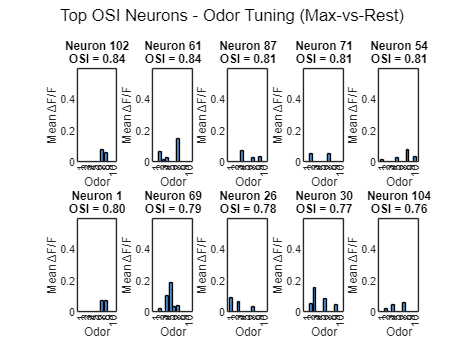


% ✅ 4. 畫出 top OSI neuron 的 tuning curves
figure;
for i = 1:length(top_neuron_idx)
    subplot(2, ceil(top_n/2), i);
    neuron_id = top_neuron_idx(i);
    bar(mean_responses(neuron_id, :), 'FaceColor', [0.3 0.6 0.9]);
    title(sprintf('Neuron %d\nOSI = %.2f', neuron_id, OSI(neuron_id)));
    xlabel('Odor'); ylabel('Mean ΔF/F');
    ylim([0 max(mean_responses(:))*1.1]);
end
sgtitle('Top OSI Neurons - Odor Tuning (Max-vs-Rest)');

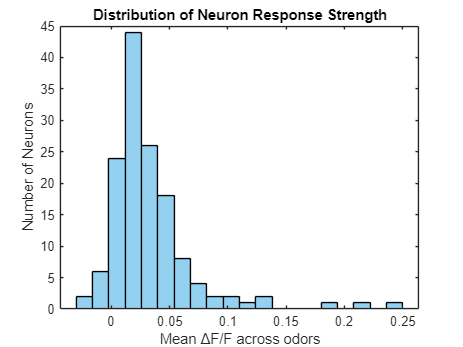

% 🎯 Distribution of Mean ΔF/F across all neurons (response strength)

% 計算每個 neuron 對所有 odor 的平均反應強度
mean_strength = mean(mean_responses, 2, 'omitnan');  % size = [n_neurons × 1]

% 繪製 histogram
figure;
histogram(mean_strength, 20, 'FaceColor', [0.3 0.7 0.9]);
xlabel('Mean ΔF/F across odors');
ylabel('Number of Neurons');
title('Distribution of Neuron Response Strength');

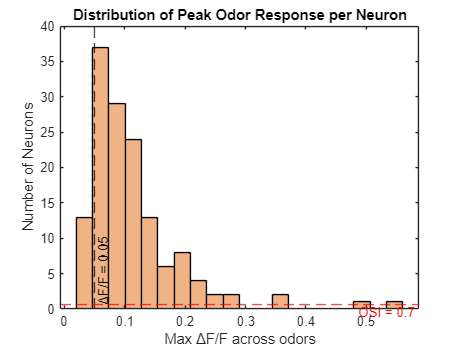

max_strength = max(mean_responses, [], 2);

figure;
histogram(max_strength, 20, 'FaceColor', [0.9 0.5 0.2]);
xlabel('Max ΔF/F across odors');
ylabel('Number of Neurons');
title('Distribution of Peak Odor Response per Neuron');
hold on;
xline(0.05, '--k', 'ΔF/F = 0.05', 'LabelVerticalAlignment','bottom');
yline(0.7, '--r', 'OSI = 0.7', 'LabelVerticalAlignment','bottom');
hold off

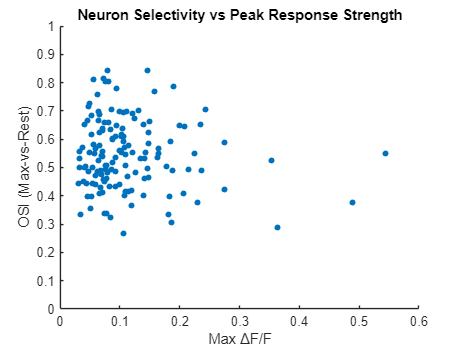

scatter(max_strength, OSI, 20, 'filled');
xlabel('Max ΔF/F');
ylabel('OSI (Max-vs-Rest)');
title('Neuron Selectivity vs Peak Response Strength');
ylim([0 1])

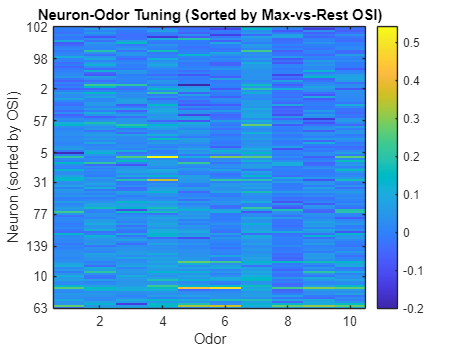

% --------------------------------------------
% 🎨 OSI sorted heatmap of neuron × odor
% --------------------------------------------

% 排序 neuron：由高 OSI → 低 OSI
[~, osi_sorted_idx] = sort(OSI, 'descend');

% 重新排列 mean_responses
sorted_mean_responses = mean_responses(osi_sorted_idx, :);

% 繪製 heatmap
figure;
imagesc(sorted_mean_responses);
xlabel('Odor');
ylabel('Neuron (sorted by OSI)');
title('Neuron-Odor Tuning (Sorted by Max-vs-Rest OSI)');
colorbar;

% Y 軸刻度調整（可選）
yticks(round(linspace(1, length(osi_sorted_idx), 10)));
yticklabels(osi_sorted_idx(round(linspace(1, length(osi_sorted_idx), 10))));

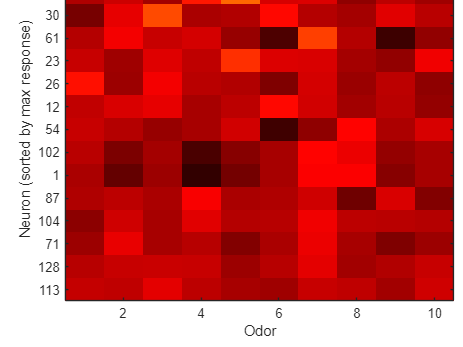

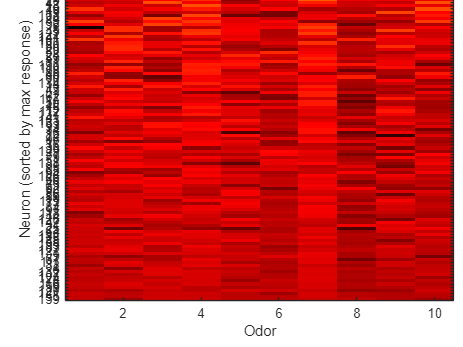

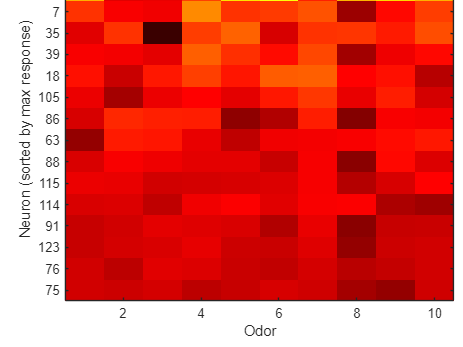

% --------------------------------------------
% 🎨 分段畫出 OSI heatmap，並在群組內依 max response 排序
% --------------------------------------------

% 分群依據 OSI
group_high = find(OSI > 0.7);
group_mid = find(OSI <= 0.7 & OSI >= 0.4);
group_low = find(OSI < 0.4);

groups = {group_high, group_mid, group_low};
group_names = {'High OSI (>0.7)', 'Medium OSI (0.4–0.7)', 'Low OSI (<0.4)'};

% colormap 統一
cmap_range = [min(mean_responses(:)), max(mean_responses(:))];

% 畫圖
for i = 1:3
    idx = groups{i};
    if isempty(idx)
        fprintf('%s group is empty.\n', group_names{i});
        continue;
    end

    data = mean_responses(idx, :);  % n_neuron × n_odor
    max_resp = max(data, [], 2);    % 每個 neuron 的 max odor response
    [~, sort_idx] = sort(max_resp, 'descend');
    
    sorted_data = data(sort_idx, :);
    sorted_neuron_ids = idx(sort_idx);

    figure;
    imagesc(sorted_data, cmap_range);
    colormap hot;
    colorbar;
    xlabel('Odor');
    ylabel('Neuron (sorted by max response)');
    title(['Neuron-Odor Tuning: ' group_names{i}]);
    yticks(1:length(sorted_neuron_ids));
    yticklabels(sorted_neuron_ids);  % 顯示原始 neuron index
end

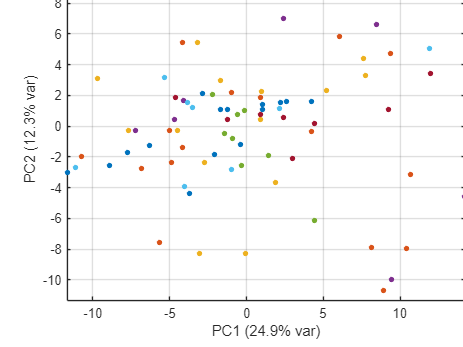

% --------------------------------------------
% 🎯 PCA 降維分析 - Aim 3
% --------------------------------------------

% 準備資料：每一筆 trial 是一個樣本
X = trial_responses';              % (n_trials × n_neurons)
Y = odor_onset_labels(:);         % 氣味標籤 (n_trials × 1)

% 移除包含 NaN 的 trial
valid_trials = all(~isnan(X), 2);
X_clean = X(valid_trials, :);
Y_clean = Y(valid_trials);

% Z-score normalization（每個 neuron mean=0, std=1）
X_norm = zscore(X_clean);

% PCA 降維
[coeff, score, ~, ~, explained] = pca(X_norm);

% --------------------------------------------
% 📊 繪製前兩主成分
% --------------------------------------------
figure;
gscatter(score(:,1), score(:,2), Y_clean, lines(10), '.', 12);
xlabel(sprintf('PC1 (%.1f%% var)', explained(1)));
ylabel(sprintf('PC2 (%.1f%% var)', explained(2)));
title('PCA of Neural Population Activity (per trial)');
legend('Location', 'bestoutside');
axis equal;
grid on;

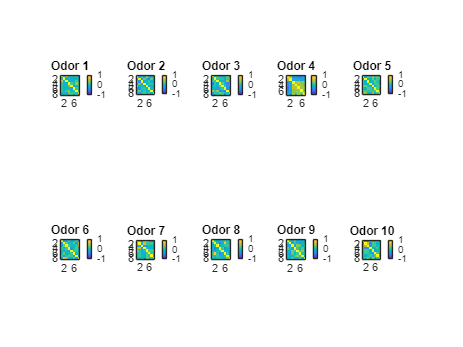

% --------------------------------------------
% 🎯 Trial-to-trial similarity analysis (within each odor)
% --------------------------------------------
n_odors = 10;
n_trials_total = size(trial_responses, 2);
similarity_per_odor = zeros(n_odors, 1);  % Output: similarity score per odor

figure;
for odor = 1:n_odors
    trial_idx = find(odor_onset_labels == odor);
    data = trial_responses(:, trial_idx)';

    % Remove NaN trials
    data = data(~any(isnan(data), 2), :);

    if size(data, 1) < 3
        similarity_per_odor(odor) = NaN;
        continue;
    end

    % Center each trial vector (subtract mean of each row)
    data = data - mean(data, 2);

    R = corr(data');

    upper_vals = triu(R, 1);
    upper_vals = upper_vals(upper_vals ~= 0);

    similarity_per_odor(odor) = mean(upper_vals);

    subplot(2, 5, odor);
    imagesc(R, [-1 1]);
    axis square;
    title(sprintf('Odor %d', odor));
    colorbar;
end


% Summary plot
figure;
bar(similarity_per_odor, 'FaceColor', [0.2 0.6 0.8]);
xlabel('Odor'); ylabel('Mean Trial-to-Trial Similarity (Centered)');
title('Odor Consistency Across Trials (Centered)');
ylim([-1 1]);

disp(size(trial_responses));

   142    80



disp(['Number of NaNs in trial_responses: ', num2str(sum(isnan(trial_responses(:))))]);

Number of NaNs in trial_responses: 142


n_odors = 10;
for odor = 1:n_odors
    idx = find(odor_onset_labels == odor);
    fprintf('Odor %d: %d trials\n', odor, numel(idx));
end

Odor 1: 8 trials
Odor 2: 8 trials
Odor 3: 8 trials
Odor 4: 8 trials
Odor 5: 8 trials
Odor 6: 8 trials
Odor 7: 8 trials
Odor 8: 8 trials
Odor 9: 8 trials
Odor 10: 8 trials


for odor = 1:n_odors
    idx = find(odor_onset_labels == odor);
    trial_data = trial_responses(:, idx)';
    trial_data_clean = trial_data(~any(isnan(trial_data), 2), :);
    fprintf('Odor %d: %d valid trials after NaN filtering\n', odor, size(trial_data_clean,1));
end

Odor 1: 8 valid trials after NaN filtering
Odor 2: 8 valid trials after NaN filtering
Odor 3: 8 valid trials after NaN filtering
Odor 4: 7 valid trials after NaN filtering
Odor 5: 8 valid trials after NaN filtering
Odor 6: 8 valid trials after NaN filtering
Odor 7: 8 valid trials after NaN filtering
Odor 8: 8 valid trials after NaN filtering
Odor 9: 8 valid trials after NaN filtering
Odor 10: 8 valid trials after NaN filtering


% 隨便取一個 odor 的 trial（例如 odor 3）
idx = find(odor_onset_labels == 3);
data = trial_responses(:, idx)';

% 移除 NaN
data = data(~any(isnan(data), 2), :);

% 檢查每個 neuron 的 std
neuron_std = std(data, 0, 1);
disp('Std of each neuron across trials:');

Std of each neuron across trials:


disp(neuron_std(1:10));  % 看前 10 個 neuron 的 std

    0.2078    0.1290    0.2707    0.4971    0.4772    0.4077    0.1941    0.0563    0.0631    0.1741



disp(similarity_per_odor);

    0.0298
   -0.0177
   -0.0216
    0.0660
    0.0981
    0.0142
    0.0322
   -0.0051
   -0.0058
    0.0221

